# MINI-PROJECT 2: 

# ***TRAFFIC ENGINEERING OF TELECOMMUNICATION NETWORKS***

Pedro Caio

17/12/2024

clearvars; close all; clc;

load("InputDataProject2.mat", "L", "Links", "Nodes", "T");
nNodes= size(Nodes,1);
nLinks= size(Links,1);
nFlows= size(T,1);
nFlows_unicast = nnz(T(:,1) == 1 | T(:,1) == 2);
nFlows_unicast1 = nnz(T(:,1) == 1);

v = 2e5;
D = L/v; % propagation delay

## Task 3

Consider now that the traffic flows of the unicast service $s = 2$ must be protected by a $1:1$  protection mechanism based on a pair of link disjoint routing paths (like before, the traffic flows of the unicast service $s = 1$ must be assigned with a single routing path). To generate the  candidate pairs of link disjoint paths, use the provided MATLAB function with the `costMatrix` defined by the propagation delays of the links (consider the first path of each pair as a candidate working path and the second path of each pair as a candidate protection paths): 

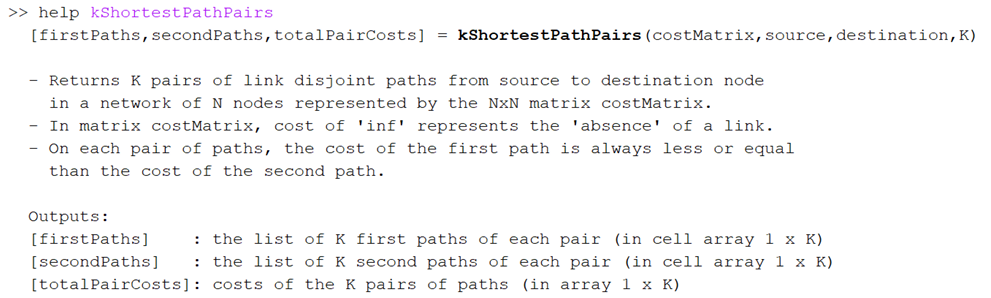

To solve the problem of minimizing the worst link load of the network (considering the load of a link given by the load of the working paths plus the reservation for the backup paths), use a Multi Start Hill Climbing algorithm with initial Greedy Randomized solutions and with a  stopping criterion defined by a given running time. Besides the found best solution, the algorithm must also output the same performance parameters as defined in Task 2. 

help kShortestPathPairs

  [firstPaths,secondPaths,totalPairCosts] = kShortestPathPairs(costMatrix,source,destination,K)
 
  - Returns K pairs of link disjoint paths from source to destination node
    in a network of N nodes represented by the NxN matrix costMatrix.
  - In matrix costMatrix, cost of 'inf' represents the 'absence' of a link.
  - On each pair of paths, the cost of the first path is always less or equal
    than the cost of the second path. 
  
  Outputs: 
  [firstPaths]    : the list of K first paths of each pair (in cell array 1 x K)
  [secondPaths]   : the list of K second paths of each pair (in cell array 1 x K)
  [totalPairCosts]: costs of the K pairs of paths (in array 1 x K)



### **3.a.**

Run the algorithm for $60$ seconds with $k = 12$ candidate paths for each traffic flow of unicast service $s = 1$ and with $k = 12$ candidate pairs of link disjoint paths for each traffic flow of unicast service $s = 2$. Consider that the anycast nodes of the anycast service are network nodes $3$ and $10$. Indicate the worst round-trip delay and the average round trip delay of each service$^1$ (presenting all values in milliseconds) and the worst link load of  the network. Indicate also the algorithm performance parameters. 

**Answer:**

anycastNodes = [3, 10];
unicastservices = [1, 2];

k=12;
protectedservices = 2;
k_pairs = k;

[sP,nSP,totalCosts_unicast_a, totalCosts_anycast_a,T] = createPathFlowsPairs(D,T,k,unicastservices,anycastNodes, protectedservices, k_pairs);

timeLimit = 60;

[bestSol,tbestSol,bestObjective,totalNCycles, bestNCycles,avObjective] = AlgorithmDPair(nNodes,Links,T,sP,nSP,timeLimit, unicastservices, protectedservices);

fprintf("Total nº Cycles = %d\n", totalNCycles);

Total nº Cycles = 181


fprintf("Running time at which the algorithm obtains its best solution = %.2f s\n", tbestSol);

Running time at which the algorithm obtains its best solution = 0.32 s


fprintf("The number of cycles at which the algorithm obtains its best solution. = %d\n", bestNCycles);

The number of cycles at which the algorithm obtains its best solution. = 1



best_totalCosts_unicast1_a = zeros(1,nFlows_unicast1);
best_totalCosts_unicast2_a = zeros(1,nFlows_unicast-nFlows_unicast1);

% the worst and average round-trip delay should be only computed over the
% working paths of the flows, so the totalCost should not have the backup
% load
for f = 1:nFlows_unicast
    [shortestPath, totalCost] = kShortestPath(D,T(f,2),T(f,3),k);
    totalCosts_unicast_a(f,:) = totalCost;
end

for f=1:nFlows_unicast1
    best_totalCosts_unicast1_a(f) = totalCosts_unicast_a(f,bestSol(f));
end

for f= nFlows_unicast1+1:nFlows_unicast
    i = f-nFlows_unicast1;
    best_totalCosts_unicast2_a(i) = totalCosts_unicast_a(f, bestSol(f));
end

fprintf("Anycast nodes= %s\n", num2str(anycastNodes))

Anycast nodes= 3  10



fprintf("Worst round-trip delay (unicast service s=1) = %.2f ms\n", max(best_totalCosts_unicast1_a*2)*1e3)

Worst round-trip delay (unicast service s=1) = 11.27 ms


fprintf("Average round-trip delay (unicast service s=1) = %.2f ms\n", mean(best_totalCosts_unicast1_a*2)*1e3)

Average round-trip delay (unicast service s=1) = 6.50 ms



fprintf("Worst round-trip delay (unicast service s=2) = %.2f ms\n", max(best_totalCosts_unicast2_a*2)*1e3)

Worst round-trip delay (unicast service s=2) = 12.00 ms


fprintf("Average round-trip delay (unicast service s=2) = %.2f ms\n", mean(best_totalCosts_unicast2_a*2)*1e3)

Average round-trip delay (unicast service s=2) = 6.02 ms



fprintf("Worst round-trip delay (anycast service) = %.2f ms\n", max(totalCosts_anycast_a*2)*1e3)

Worst round-trip delay (anycast service) = 6.16 ms


fprintf("Average round-trip delay (anycast service) = %.2f ms\n", mean(totalCosts_anycast_a*2)*1e3)

Average round-trip delay (anycast service) = 3.43 ms



fprintf("Worst link load of the network = %.2f Gbps\n", bestObjective);

Worst link load of the network = 96.10 Gbps


### **3.b.**

Repeat experiment **3.a** with the anycast nodes selected in experiment **1.c**.

**Answer:**

anycastNodes = [1, 6];
unicastservices = [1, 2];

k=12;
protectedservices = 2;
k_pairs = k;

[sP,nSP,totalCosts_unicast_a, totalCosts_anycast_a,T] = createPathFlowsPairs(D,T,k,unicastservices,anycastNodes, protectedservices, k_pairs);

timeLimit = 60;

[bestSol,tbestSol,bestObjective,totalNCycles, bestNCycles,avObjective] = AlgorithmDPair(nNodes,Links,T,sP,nSP,timeLimit, unicastservices, protectedservices);

fprintf("Total nº Cycles = %d\n", totalNCycles);

Total nº Cycles = 208


fprintf("Running time at which the algorithm obtains its best solution = %.2f s\n", tbestSol);

Running time at which the algorithm obtains its best solution = 0.27 s


fprintf("The number of cycles at which the algorithm obtains its best solution. = %d\n", bestNCycles);

The number of cycles at which the algorithm obtains its best solution. = 1



best_totalCosts_unicast1_a = zeros(1,nFlows_unicast1);
best_totalCosts_unicast2_a = zeros(1,nFlows_unicast-nFlows_unicast1);

% the worst and average round-trip delay should be only computed over the
% working paths of the flows, so the totalCost should not have the backup
% load
for f = 1:nFlows_unicast
    [shortestPath, totalCost] = kShortestPath(D,T(f,2),T(f,3),k);
    totalCosts_unicast_a(f,:) = totalCost;
end

for f=1:nFlows_unicast1
    best_totalCosts_unicast1_a(f) = totalCosts_unicast_a(f,bestSol(f));
end

for f= nFlows_unicast1+1:nFlows_unicast
    i = f-nFlows_unicast1;
    best_totalCosts_unicast2_a(i) = totalCosts_unicast_a(f, bestSol(f));
end

fprintf("Anycast nodes= %s\n", num2str(anycastNodes))

Anycast nodes= 1  6



fprintf("Worst round-trip delay (unicast service s=1) = %.2f ms\n", max(best_totalCosts_unicast1_a*2)*1e3)

Worst round-trip delay (unicast service s=1) = 11.98 ms


fprintf("Average round-trip delay (unicast service s=1) = %.2f ms\n", mean(best_totalCosts_unicast1_a*2)*1e3)

Average round-trip delay (unicast service s=1) = 5.94 ms



fprintf("Worst round-trip delay (unicast service s=2) = %.2f ms\n", max(best_totalCosts_unicast2_a*2)*1e3)

Worst round-trip delay (unicast service s=2) = 11.07 ms


fprintf("Average round-trip delay (unicast service s=2) = %.2f ms\n", mean(best_totalCosts_unicast2_a*2)*1e3)

Average round-trip delay (unicast service s=2) = 6.25 ms



fprintf("Worst round-trip delay (anycast service) = %.2f ms\n", max(totalCosts_anycast_a*2)*1e3)

Worst round-trip delay (anycast service) = 6.41 ms


fprintf("Average round-trip delay (anycast service) = %.2f ms\n", mean(totalCosts_anycast_a*2)*1e3)

Average round-trip delay (anycast service) = 3.02 ms




fprintf("Worst link load of the network = %.2f Gbps\n", bestObjective);

Worst link load of the network = 96.10 Gbps


### **3.c.**

Repeat experiment **3.a** with the anycast nodes selected in experiment **1.d**.

**Answer:**

anycastNodes = [4, 12];
unicastservices = [1, 2];

k=12;
protectedservices = 2;
k_pairs = k;

[sP,nSP,totalCosts_unicast_a, totalCosts_anycast_a,T] = createPathFlowsPairs(D,T,k,unicastservices,anycastNodes, protectedservices, k_pairs);

timeLimit = 60;

[bestSol,tbestSol,bestObjective,totalNCycles, bestNCycles,avObjective] = AlgorithmDPair(nNodes,Links,T,sP,nSP,timeLimit, unicastservices, protectedservices);

fprintf("Total nº Cycles = %d\n", totalNCycles);

Total nº Cycles = 208


fprintf("Running time at which the algorithm obtains its best solution = %.2f s\n", tbestSol);

Running time at which the algorithm obtains its best solution = 0.42 s


fprintf("The number of cycles at which the algorithm obtains its best solution. = %d\n", bestNCycles);

The number of cycles at which the algorithm obtains its best solution. = 1



best_totalCosts_unicast1_a = zeros(1,nFlows_unicast1);
best_totalCosts_unicast2_a = zeros(1,nFlows_unicast-nFlows_unicast1);

% the worst and average round-trip delay should be only computed over the
% working paths of the flows, so the totalCost should not have the backup
% load
for f = 1:nFlows_unicast
    [shortestPath, totalCost] = kShortestPath(D,T(f,2),T(f,3),k);
    totalCosts_unicast_a(f,:) = totalCost;
end

for f=1:nFlows_unicast1
    best_totalCosts_unicast1_a(f) = totalCosts_unicast_a(f,bestSol(f));
end

for f= nFlows_unicast1+1:nFlows_unicast
    i = f-nFlows_unicast1;
    best_totalCosts_unicast2_a(i) = totalCosts_unicast_a(f, bestSol(f));
end

fprintf("Anycast nodes= %s\n", num2str(anycastNodes))

Anycast nodes= 4  12



fprintf("Worst round-trip delay (unicast service s=1) = %.2f ms\n", max(best_totalCosts_unicast1_a*2)*1e3)

Worst round-trip delay (unicast service s=1) = 11.06 ms


fprintf("Average round-trip delay (unicast service s=1) = %.2f ms\n", mean(best_totalCosts_unicast1_a*2)*1e3)

Average round-trip delay (unicast service s=1) = 6.22 ms



fprintf("Worst round-trip delay (unicast service s=2) = %.2f ms\n", max(best_totalCosts_unicast2_a*2)*1e3)

Worst round-trip delay (unicast service s=2) = 12.30 ms


fprintf("Average round-trip delay (unicast service s=2) = %.2f ms\n", mean(best_totalCosts_unicast2_a*2)*1e3)

Average round-trip delay (unicast service s=2) = 6.81 ms



fprintf("Worst round-trip delay (anycast service) = %.2f ms\n", max(totalCosts_anycast_a*2)*1e3)

Worst round-trip delay (anycast service) = 4.42 ms


fprintf("Average round-trip delay (anycast service) = %.2f ms\n", mean(totalCosts_anycast_a*2)*1e3)

Average round-trip delay (anycast service) = 2.90 ms



fprintf("Worst link load of the network = %.2f Gbps\n", bestObjective);

Worst link load of the network = 96.10 Gbps


### **3.d.**

Repeat experiment **3.a** with the anycast nodes selected in experiment **1.e**.

**Answer:**

anycastNodes = [5, 14];
unicastservices = [1, 2];

k=12;
protectedservices = 2;
k_pairs = k;

[sP,nSP,totalCosts_unicast_a, totalCosts_anycast_a,T] = createPathFlowsPairs(D,T,k,unicastservices,anycastNodes, protectedservices, k_pairs);

timeLimit = 60;

[bestSol,tbestSol,bestObjective,totalNCycles, bestNCycles,avObjective] = AlgorithmDPair(nNodes,Links,T,sP,nSP,timeLimit, unicastservices, protectedservices);

fprintf("Total nº Cycles = %d\n", totalNCycles);

Total nº Cycles = 214


fprintf("Running time at which the algorithm obtains its best solution = %.2f s\n", tbestSol);

Running time at which the algorithm obtains its best solution = 0.27 s


fprintf("The number of cycles at which the algorithm obtains its best solution. = %d\n", bestNCycles);

The number of cycles at which the algorithm obtains its best solution. = 1



best_totalCosts_unicast1_a = zeros(1,nFlows_unicast1);
best_totalCosts_unicast2_a = zeros(1,nFlows_unicast-nFlows_unicast1);

% the worst and average round-trip delay should be only computed over the
% working paths of the flows, so the totalCost should not have the backup
% load
for f = 1:nFlows_unicast
    [shortestPath, totalCost] = kShortestPath(D,T(f,2),T(f,3),k);
    totalCosts_unicast_a(f,:) = totalCost;
end

for f=1:nFlows_unicast1
    best_totalCosts_unicast1_a(f) = totalCosts_unicast_a(f,bestSol(f));
end

for f= nFlows_unicast1+1:nFlows_unicast
    i = f-nFlows_unicast1;
    best_totalCosts_unicast2_a(i) = totalCosts_unicast_a(f, bestSol(f));
end

fprintf("Anycast nodes= %s\n", num2str(anycastNodes))

Anycast nodes= 5  14



fprintf("Worst round-trip delay (unicast service s=1) = %.2f ms\n", max(best_totalCosts_unicast1_a*2)*1e3)

Worst round-trip delay (unicast service s=1) = 11.98 ms


fprintf("Average round-trip delay (unicast service s=1) = %.2f ms\n", mean(best_totalCosts_unicast1_a*2)*1e3)

Average round-trip delay (unicast service s=1) = 6.14 ms



fprintf("Worst round-trip delay (unicast service s=2) = %.2f ms\n", max(best_totalCosts_unicast2_a*2)*1e3)

Worst round-trip delay (unicast service s=2) = 11.07 ms


fprintf("Average round-trip delay (unicast service s=2) = %.2f ms\n", mean(best_totalCosts_unicast2_a*2)*1e3)

Average round-trip delay (unicast service s=2) = 5.90 ms



fprintf("Worst round-trip delay (anycast service) = %.2f ms\n", max(totalCosts_anycast_a*2)*1e3)

Worst round-trip delay (anycast service) = 4.90 ms


fprintf("Average round-trip delay (anycast service) = %.2f ms\n", mean(totalCosts_anycast_a*2)*1e3)

Average round-trip delay (anycast service) = 2.52 ms



fprintf("Worst link load of the network = %.2f Gbps\n", bestObjective);

Worst link load of the network = 96.10 Gbps


### **3.e.**

Compare the results obtained in all experiments of this Task 3 and of the previous Task 2  and draw all meaningful conclusions both concerning the differences between the  solutions and the differences between the performance of the algorithm.

**Answer:**

## Footnotes

$^1$: In the unicast service $s = 2$, the worst round-trip delay and the average round-trip delay should be only computed  over the working paths of the flows (the paths supporting the traffic when there are no link failures). 

## References:

None

## Internal Functions: